# P1

clc
clear
close all

% 基本参数
Gqn0=[16,64,256,1024,4096,16384,65536,262144]*1e-6; % 分别为A、B、C、D、E、F、G、H级路面
vv=[10,20,40,60];   % 车速m/s

v = vv(1); % 选择车速
n0=0.1;    % 参考空间频率
n1=0.01;   % 下截止空间频率
f0=n1*v;   % 下截止频率 f=nv

% simulink增益参数设定
k1=2*pi*n0*sqrt(Gqn0(1)*v);
k2=2*pi*f0;

% white noise参数设置
noise_power = 0.5;       % 噪声功率
sample_time = 1/(10*v);  % 采样时间
seed = 23341;            % 随机种子

% 运行simulink模型
options=simset('Srcworkspace','current');
out=sim('P1_son.slx',[0,20]);

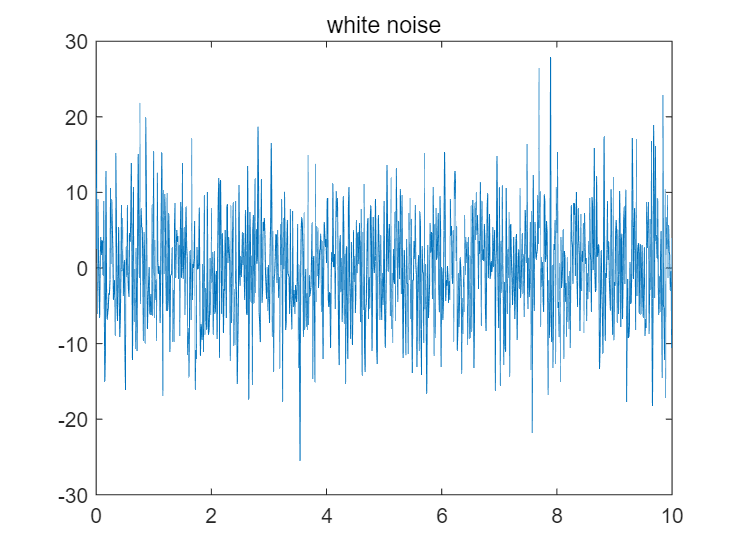

% 绘制白噪声
figure(1)
noise_x = out.noise.Time;
noise_y = out.noise.Data;
% plot(noise_x,noise_y);
% title('white noise');

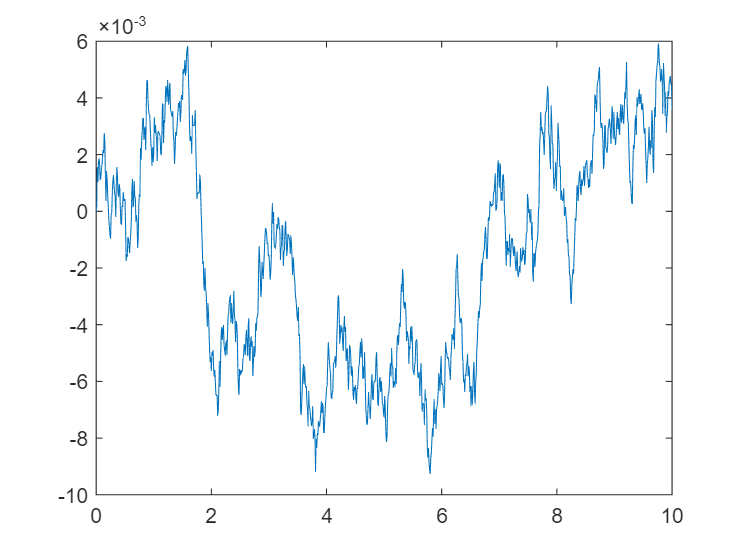


% 绘制路面不平度随时间变化
figure(2)
time           = out.simout.Time;
roud_roughness = out.simout.Data;
plot(time,roud_roughness);